## Part 1 : Getting started with Matlab

### Question 1 : What is frequency sampling?

In signal processing, **sampling** is the reduction of a continuous-time signal to a discrete-time signal. A common example is the conversion of a sound wave (a continuous signal) to a sequence of samples (a discrete-time signal).

For functions that vary with time, let *s*(*t*) be a continuous function (or "signal") to be sampled, and let sampling be performed by measuring the value of the continuous function every ***T*** seconds, which is called the **sampling interval** or **the sampling period**.

The **sampling frequency** or **sampling rate, fs,** is the average number of samples obtained in one second (*samples per second*), thus **fs = 1/T**.

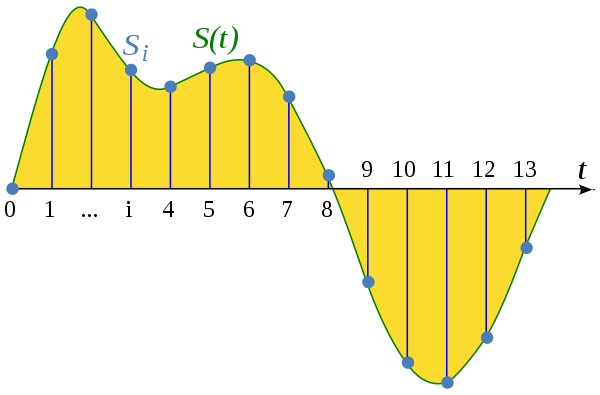

The green curve indicates continuous signal and blue dots indicate the samples.

### Question 2 : Draw y = cos(2πft) in time domain using plot function

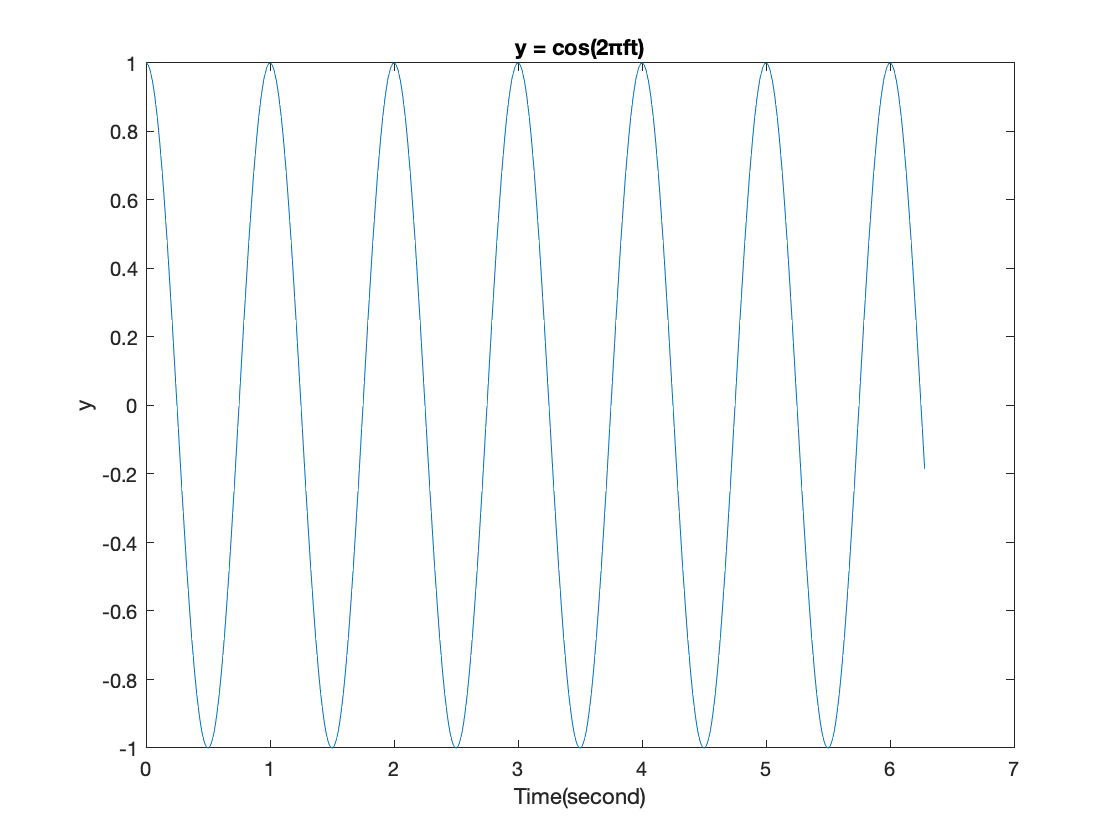

f = 1;
time_step = 0.01;
%% Sample Frequency
fs = 1/time_step;
t = 0:time_step:2*pi;
y = cos(2*pi*f*t);
plot(t,y)
xlabel("Time(second)");
ylabel("y");
title("y = cos(2πft)");

## Question 3: Build frequency vector

numel(y) calculates number of elements in y vector.

The second line generates numel(y) points and the space between the points is $\frac{\textrm{fs}}{\textrm{numel}\left(y\right)-1}$ . 

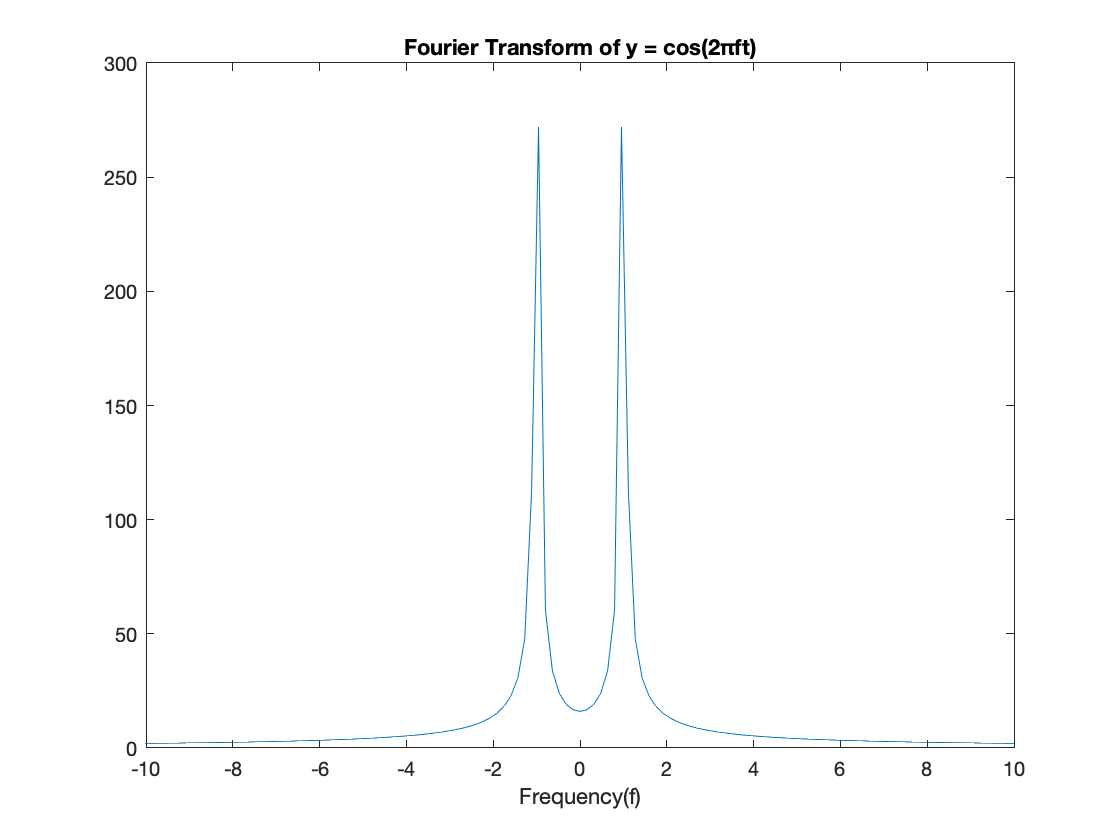

f = linspace(-fs/2,fs/2,numel(y));
yfft = fft(y);
yfft_shitft = fftshift(yfft);
plot(f,abs(yfft_shitft));
title("Fourier Transform of y = cos(2πft)");
xlabel("Frequency(f)");
xlim([-10 10]);

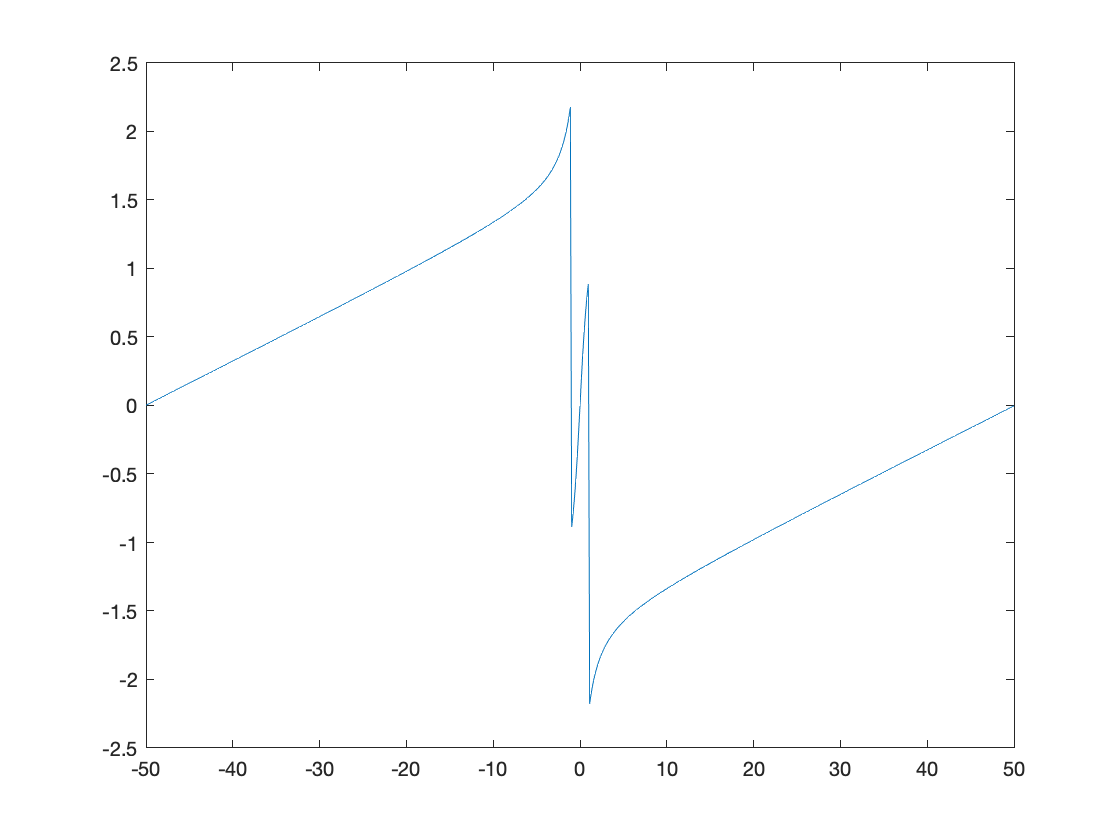

plot(f,angle(yfft_shitft))

## Question 4 : 